Cart-Pole con variabili continue

env = rlPredefinedEnv("CartPole-Continuous");
obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);

criticNet  = [
    featureInputLayer(obsInfo.Dimension(1),"Name","input")
    fullyConnectedLayer(32,"Name","fc_1")
    reluLayer("Name","relu")
    fullyConnectedLayer(32,"Name","fc_2")
    reluLayer("Name","relu_1")
    fullyConnectedLayer(1,"Name","fc")];

criticNet = dlnetwork(criticNet);
critic = rlValueFunction(criticNet,obsInfo);

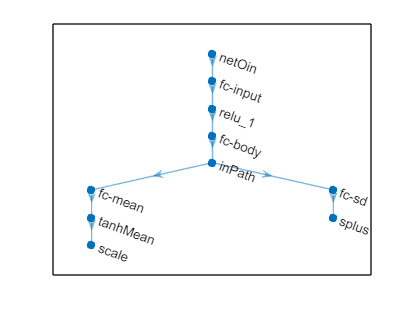

% Input path layers
inPath = [ 
    featureInputLayer( ...
        prod(obsInfo.Dimension), ...
        Name="netOin")
    fullyConnectedLayer(32,"Name","fc-input")
    reluLayer("Name","relu_1")
    fullyConnectedLayer(32,"Name","fc-body")
    reluLayer("Name","inPath")
    ];

% Path layers for mean value 
meanPath = [ 
    fullyConnectedLayer(1,"Name","fc-mean")
    tanhLayer(Name="tanhMean");
    scalingLayer(Name="scale", Scale=actInfo.UpperLimit) 
    ];

% Path layers for standard deviations
sdevPath = [ 
    fullyConnectedLayer(actInfo.Dimension(1),"Name","fc-sd")
    softplusLayer(Name="splus") 
    ];

% Add layers to network object
net = layerGraph(inPath);
net = addLayers(net,meanPath);
net = addLayers(net,sdevPath);

% Connect layers
net = connectLayers(net,"inPath","fc-mean/in");
net = connectLayers(net,"inPath","fc-sd/in");

% Plot the network
plot(net)

actorNet = dlnetwork(net);

actor = rlContinuousGaussianActor(actorNet, obsInfo, actInfo, ...
    ActionMeanOutputNames="scale",...
    ActionStandardDeviationOutputNames="splus",...
    ObservationInputNames="netOin");

%agent = rlACAgent(actor,critic);
agent = rlPPOAgent(actor,critic);

agent.AgentOptions.EntropyLossWeight = 0.01;
agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-3;
agent.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-2;


trainOpts = rlTrainingOptions(...
    MaxEpisodes=1000,...
    MaxStepsPerEpisode=500,...
    Verbose=false,...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=480,...
    ScoreAveragingWindowLength=30);

trainingStats = train(agent,env,trainOpts);

plot(env)
for i = 1 : 10
    simOptions = rlSimulationOptions(MaxSteps=500);
    experience = sim(env,agent,simOptions);
    totalReward = sum(experience.Reward)
end

totalReward = 495.0274

totalReward = 497.3149

totalReward = 490.9522

totalReward = 474.3621

totalReward = 496.9930

totalReward = 481.2003

totalReward = 498.6581

totalReward = 480.6490

totalReward = 481.4116

totalReward = 494.0404